clc;clear;
workingpath='/Volumes/WD_D/share/202007RM039 嗅觉实验/';
cd(workingpath);

id=fopen('嗅觉实验记录.txt');
conditions=textscan(id,'%q','whitespace','\b\t');
conditions=conditions{1};
fclose(id);
files=dir('data*.csv');
alldata=cell(1,length(files));
% middle point
m=zeros(1,length(files));
for f=1:length(files)
    % load data
    filename=files(f).name;
    % 从第二行第一列读取数据
    data=csvread(filename,1,0);
    m(f)=mean([min(data(:,2)) max(data(:,2))]);
    disp([min(data(:,2)) mean([min(data(:,2)) max(data(:,2))]) max(data(:,2)) min(data(:,3)) mean([min(data(:,3)) max(data(:,3))]) max(data(:,3))])
    data(:,3)=130-data(:,3);
    % 绘制轨迹
    % monkeyt(data(:,2),data(:,3),0.1,0.001);
    % 查看分布情况
    % length(data(data(:,2)>100,3));
    % length(data(data(:,2)<=100,3));
    % 
    % length(data(data(:,2)<=90,3));
    % length(data(data(:,2)>=110,3));
    % 
    % length(data(data(:,2)<=80,3));
    % length(data(data(:,2)>=120,3));
    % max(data(:,2));
    % min(data(:,2));
    % mean([max(data(:,2)),min(data(:,2))]);
    %保存到cell中
    alldata{f}=data;
end

    7.3455  102.7772  198.2090   50.6509   85.9780  121.3050



   38.7724  107.1697  175.5670   61.3887   82.6643  103.9400



   37.8309  108.2765  178.7220   54.1094   79.1037  104.0980



   38.3356  105.1518  171.9680   63.0501   83.0211  102.9920



## Scale

for f=1:length(files)
    data=alldata{f};
    mid=m(f);
    minvalue=min(data(:,2));
    maxvalue=max(data(:,2));
    data(data(:,2)<=mid,2)=(data(data(:,2)<=mid,2)-minvalue)*100/(mid-minvalue);    
    data(data(:,2)>mid,2)=100+(data(data(:,2)>mid,2)-mid)*100/(maxvalue-mid);    
    alldata{f}=data;
end

## 绘制轨迹

% for f=1:length(files)
%     data=alldata{f};
%     figure;
%     % 绘制轨迹
%     % monkeyt(data(:,2),data(:,3),0.1,0.001);
%     monkeyt(data(:,2),data(:,3),0,0);
%     title(conditions{f});
% end

## 整体的直方图

20200708 左：香蕉 右：5%异戊酸


   100   100



pvalue = 3.8276e-123

st =     chi2stat: 556.9738
          df: 1
       edges: [0 100 200]
           O: [29513 35532]
           E: [3.2522e+04 3.2522e+04]


    90   110



pvalue = 1.8396e-123

st =     chi2stat: 558.4365
          df: 1
       edges: [0 100 200]
           O: [28794 34751]
           E: [3.1772e+04 3.1772e+04]


    80   120



pvalue = 7.9095e-125

st =     chi2stat: 564.7187
          df: 1
       edges: [0 100 200]
           O: [27811 33705]
           E: [30758 30758]


20200709 左：白桃 右：吲哚


   100   100



pvalue = 1.5446e-60

st =     chi2stat: 269.3855
          df: 1
       edges: [0 100 200]
           O: [42540 47464]
           E: [45002 45002]


    90   110



pvalue = 9.2487e-69

st =     chi2stat: 307.1225
          df: 1
       edges: [0 100 200]
           O: [41586 46796]
           E: [44191 44191]


    80   120



pvalue = 3.8071e-31

st =     chi2stat: 134.7172
          df: 1
       edges: [0 100 200]
           O: [39831 43175]
           E: [41503 41503]


20200715 左：5%异戊酸 右：香蕉


   100   100



pvalue = 0

st =     chi2stat: 2.3001e+03
          df: 1
       edges: [0 100 200]
           O: [37808 52196]
           E: [45002 45002]


    90   110



pvalue = 0

st =     chi2stat: 2.3247e+03
          df: 1
       edges: [0 100 200]
           O: [36899 51211]
           E: [44055 44055]


    80   120



pvalue = 3.5946e-140

st =     chi2stat: 635.2562
          df: 1
       edges: [0 100 200]
           O: [34941 41929]
           E: [38435 38435]


20200716 左：吲哚 右：白桃


   100   100



pvalue = 4.2543e-142

st =     chi2stat: 644.1158
          df: 1
       edges: [0 100 200]
           O: [48809 41195]
           E: [45002 45002]


    90   110



pvalue = 1.1299e-143

st =     chi2stat: 651.3613
          df: 1
       edges: [0 100 200]
           O: [47907 40326]
           E: [4.4116e+04 4.4116e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.8628e+03
          df: 1
       edges: [0 100 200]
           O: [46396 31466]
           E: [38931 38931]


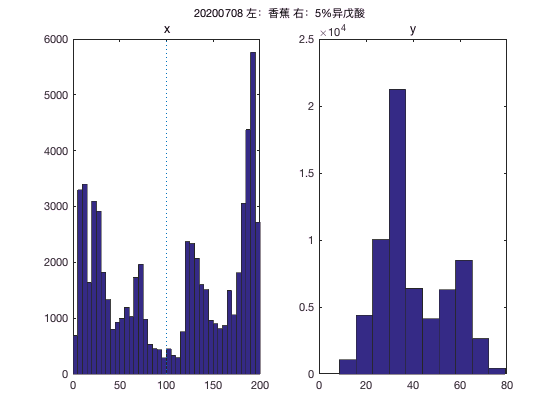

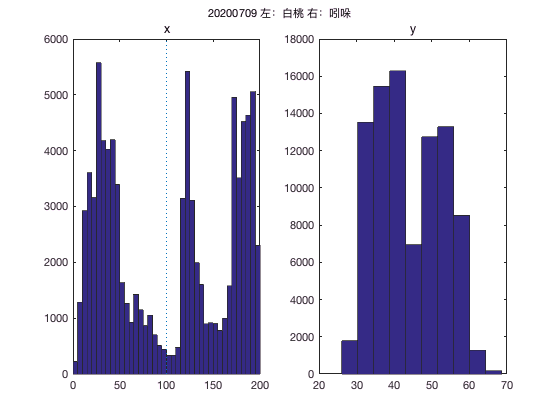

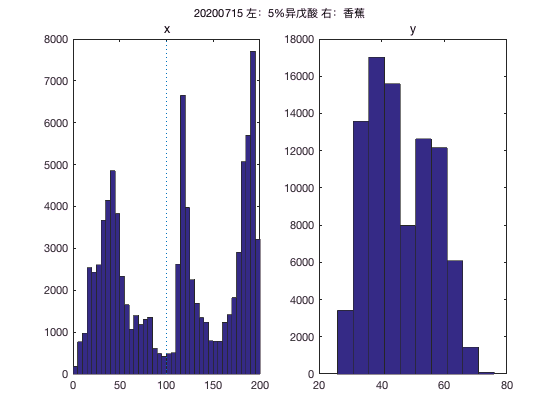

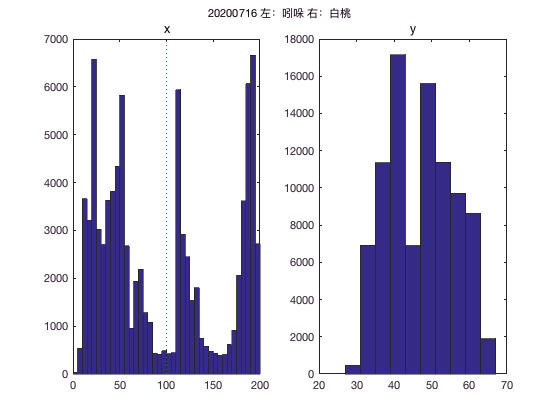

interval=5;
for f=1:length(files)
    data=alldata{f};
    % chisq test
    disp(conditions{f})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr)
    end
    figure;
    % x方向的分布
    subplot(1,2,1)
    hist(data(:,2),interval/2:interval:200-interval/2);
    line([100 100],get(gca,'Ylim'),'linestyle',':')
    title('x')
    % y方向的分布
    subplot(1,2,2)
    hist(data(:,3));
    title('y')
    suptitle(conditions{f});
end

## 合并4个条件

tic;
interval=10;
data=[alldata{1};alldata{2};alldata{3};alldata{4}];
expect=zeros(3,2);
    % chisq test
    disp('4 days');

4 days


    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr)
        expect(i/10+1,:)=st.O;
    end

   100   100



pvalue = 9.6646e-206

st =     chi2stat: 936.8319
          df: 1
       edges: [0 100 200]
           O: [158670 176387]
           E: [1.6753e+05 1.6753e+05]


    90   110



pvalue = 3.2080e-214

st =     chi2stat: 975.8382
          df: 1
       edges: [0 100 200]
           O: [155186 173084]
           E: [164135 164135]


    80   120



pvalue = 0.0178

st =     chi2stat: 5.6127
          df: 1
       edges: [0 100 200]
           O: [148979 150275]
           E: [149627 149627]


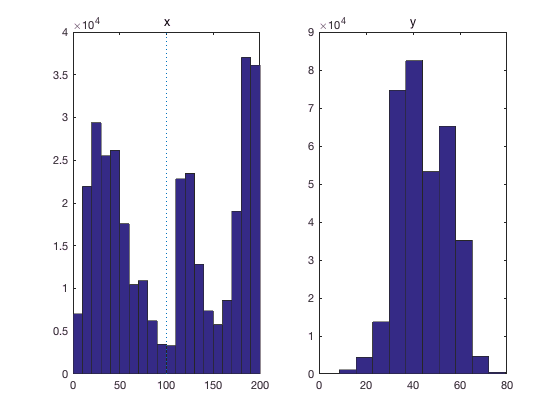


figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')

## 绘制热图

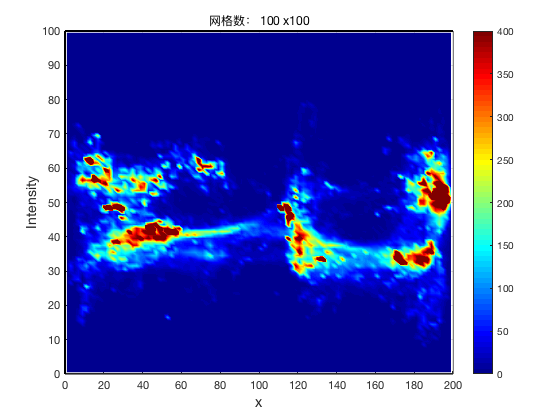

xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title(['网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');

toc;

时间已过 20.653925 秒。


## 合并两个条件-1和3合并为1的方向

tic;
interval=10;
data=alldata{3};
data(:,2)=200-data(:,2);
data=[alldata{1};data];

    % chisq test
    disp(conditions{1}(10:end))

左：香蕉 右：5%异戊酸


    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr,expect(i/10+1,:))
    end

   100   100



pvalue = 0

st =     chi2stat: 1.7753e+03
          df: 1
       edges: [0 100 200]
           O: [81709 73340]
           E: [7.3425e+04 8.1624e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.8276e+03
          df: 1
       edges: [0 100 200]
           O: [80005 71650]
           E: [7.1693e+04 7.9962e+04]


    80   120



pvalue = 5.3154e-06

st =     chi2stat: 20.7202
          df: 1
       edges: [0 100 200]
           O: [69740 68646]
           E: [6.8893e+04 6.9493e+04]


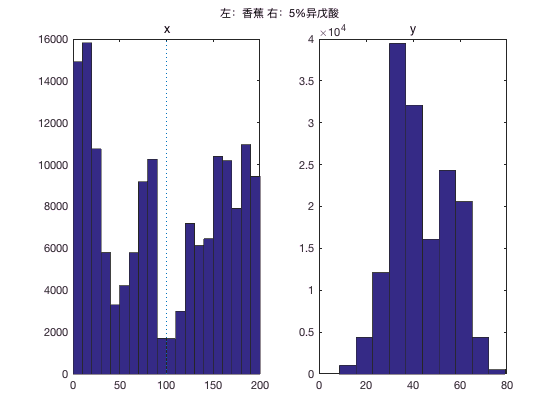


figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{1};
suptitle(t(10:end));

## 绘制热图

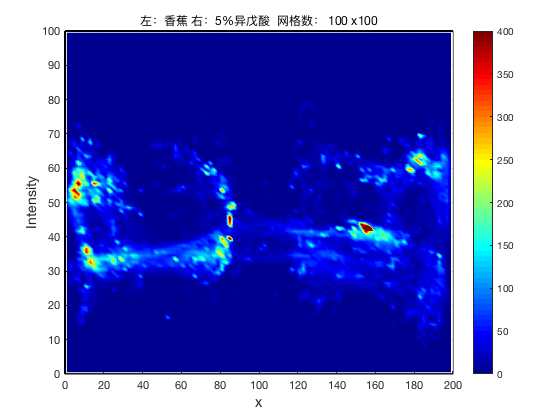

xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title([t(10:end) '  网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');

toc;

时间已过 13.280758 秒。


## 合并两个条件-2和3合并为2的方向

tic;
interval=10;
data=alldata{4};
data(:,2)=200-data(:,2);
data=[alldata{2};data];
    % chisq test
    disp(conditions{2}(10:end))

左：白桃 右：吲哚


    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr,expect(i/10+1,:))
    end

   100   100



pvalue = 1.0250e-12

st =     chi2stat: 50.7957
          df: 1
       edges: [0 100 200]
           O: [83735 96273]
           E: [8.5245e+04 9.4763e+04]


    90   110



pvalue = 4.9151e-14

st =     chi2stat: 56.7635
          df: 1
       edges: [0 100 200]
           O: [81912 94703]
           E: [8.3493e+04 9.3122e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.9206e+03
          df: 1
       edges: [0 100 200]
           O: [71297 89571]
           E: [8.0086e+04 8.0782e+04]


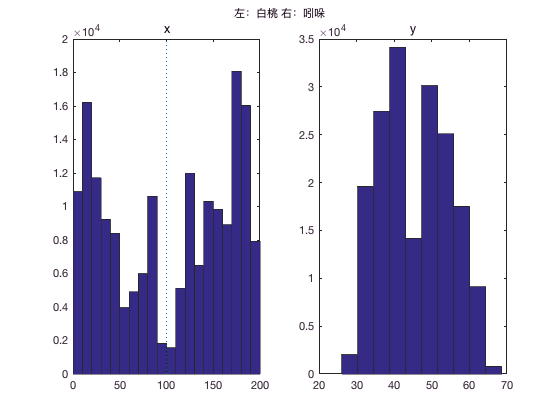

figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{2};
suptitle(t(10:end));

## 绘制热图

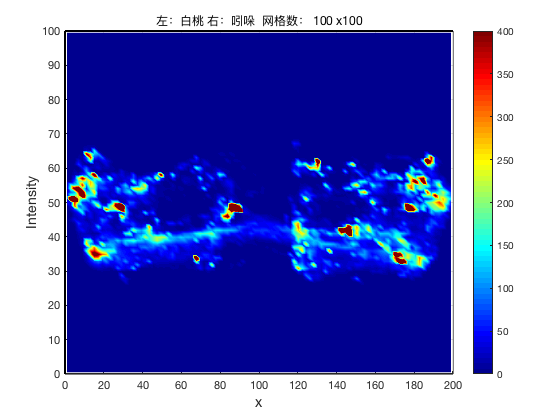

xx=data(:,2);
yy=data(:,3);

sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize);
y=linspace(0,100,gridSize);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
axis([0 200 0 100]);
h1 = gca; % 保存句柄，以便后面添加边框
% 设置颜色范围
set(gca, 'CLim', [0 400]);

% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title([t(10:end) '  网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');

toc;

时间已过 13.882003 秒。


## 合并两个条件的（只取前面一段时间）

interval=10;
timeint=10;%minute
p1=1;
p2=timeint*60*1000/40;
% 1和3合并为1的方向
data=alldata{3};
data(:,2)=200-data(:,2);
data=[alldata{1}(p1:p2,:);data(p1:p2,:)];
data=data(data(:,2)<=50|data(:,2)>=150,:);
    % chisq test
    for i=0
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr)
    end

   100   100



pvalue = 5.7160e-136

st =     chi2stat: 615.9386
          df: 1
       edges: [0 100 200]
           O: [11229 7805]
           E: [9517 9517]


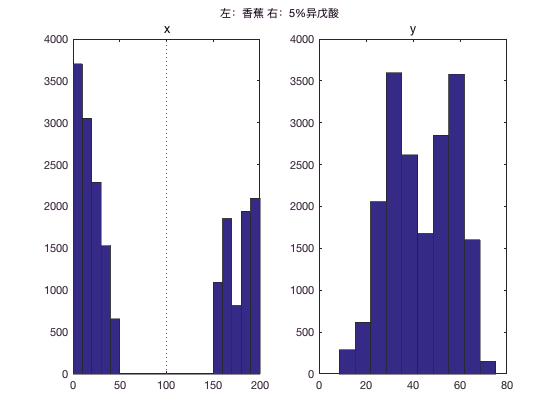

figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{1};
suptitle(t(10:end));


% 2和4合并为2的方向
data=alldata{4};
data(:,2)=200-data(:,2);
data=[alldata{2}(p1:p2,:);data(p1:p2,:)];
data=data(data(:,2)<=50|data(:,2)>=150,:);
    % chisq test
    for i=0
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr)
    end

   100   100



pvalue = 8.1480e-288

st =     chi2stat: 1.3145e+03
          df: 1
       edges: [0 100 200]
           O: [7596 12770]
           E: [10183 10183]


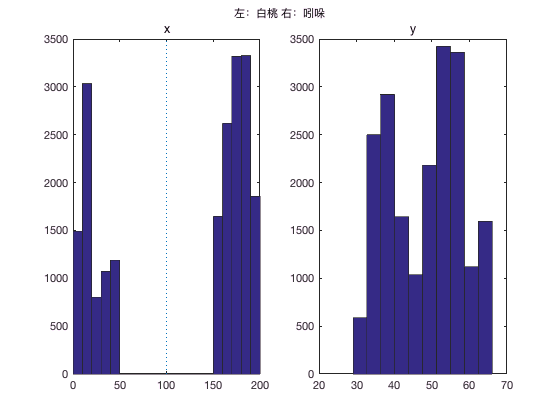

figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{2};
suptitle(t(10:end));

## 分时段的分布直方图

20200708 左：香蕉 右：5%异戊酸


-------------


100-100


        8282        8368
        6830        9820
        8403        8247
        5998        9097



  623.4374



  8.3623e-135



-------------


-------------


90-110


        7947        8703
        6704        9946
        8275        8375
        5868        9227



  566.1938



  2.1467e-122



-------------


-------------


80-120


        7642        9008
        6504       10146
        8011        8639
        5654        9441



  528.4677



  3.2282e-114



-------------


-------------


70-130


        6902        9748
        5706       10944
        7036        9614
        5219        9876



  383.6678



   7.6321e-83



-------------


-------------


60-140


        6023       10627
        4929       11721
        6390       10260
        4766       10329



  360.3894



   8.3937e-78



-------------


-------------


50-150


        5495       11155
        4155       12495
        5847       10803
        4426       10669



  466.4430



  8.9217e-101



-------------


20200709 左：白桃 右：吲哚


-------------


100-100


        5101       11549
        6627       10023
        9814        6836
       10175        6475
        7849        8801
        2974        3780



   4.4391e+03



     0



-------------


-------------


90-110


        4860       11790
        6473       10177
        9746        6904
        9916        6734
        7666        8984
        2925        3829



   4.5345e+03



     0



-------------


-------------


80-120


        4486       12164
        6171       10479
        9641        7009
        9363        7287
        7397        9253
        2773        3981



   4.6259e+03



     0



-------------


-------------


70-130


        4177       12473
        5823       10827
        9519        7131
        9014        7636
        6969        9681
        2314        4440



   5.0385e+03



     0



-------------


-------------


60-140


        3757       12893
        5410       11240
        9380        7270
        8704        7946
        6585       10065
        1631        5123



   6.1234e+03



     0



-------------


-------------


50-150


        3206       13444
        4926       11724
        9146        7504
        8214        8436
        5761       10889
        1314        5440



   6.9979e+03



     0



-------------


20200715 左：5%异戊酸 右：香蕉


-------------


100-100


        5409       11241
        6935        9715
        7179        9471
        7697        8953
        7411        9239
        3177        3577



  863.5980



  2.0085e-184



-------------


-------------


90-110


        5261       11389
        6635       10015
        7059        9591
        7600        9050
        7222        9428
        3122        3632



  894.6347



  3.8574e-191



-------------


-------------


80-120


        5076       11574
        6038       10612
        6828        9822
        7447        9203
        6785        9865
        2767        3987



  850.0833



  1.6877e-181



-------------


-------------


70-130


        4789       11861
        5681       10969
        6139       10511
        7225        9425
        6363       10287
        2262        4492



  857.6683



  3.8550e-183



-------------


-------------


60-140


        4470       12180
        5110       11540
        5519       11131
        6897        9753
        5951       10699
        2049        4705



  929.0254



  1.3898e-198



-------------


-------------


50-150


        3974       12676
        4445       12205
        4136       12514
        6304       10346
        5256       11394
        1891        4863



   1.0893e+03



  2.7898e-233



-------------


20200716 左：吲哚 右：白桃


-------------


100-100


       10026        6624
        7433        9217
       11468        5182
        7597        9053
        8346        8304
        3939        2815



   2.9510e+03



     0



-------------


-------------


90-110


        9855        6795
        7184        9466
       11338        5312
        7416        9234
        8204        8446
        3910        2844



   3.0641e+03



     0



-------------


-------------


80-120


        9515        7135
        6766        9884
       11291        5359
        7129        9521
        7836        8814
        3859        2895



   3.4932e+03



     0



-------------


-------------


70-130


        9218        7432
        6244       10406
       11247        5403
        5302       11348
        7101        9549
        3818        2936



   5.7751e+03



     0



-------------


-------------


60-140


        8989        7661
        5858       10792
       11201        5449
        4030       12620
        6196       10454
        3767        2987



   8.1714e+03



     0



-------------


-------------


50-150


        8091        8559
        5184       11466
        7804        8846
        2974       13676
        4889       11761
        2602        4152



   4.9091e+03



     0



-------------


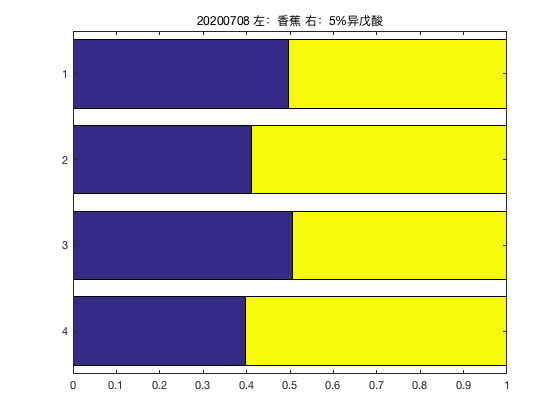

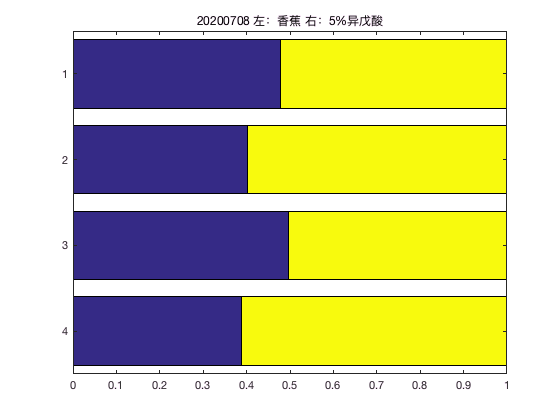

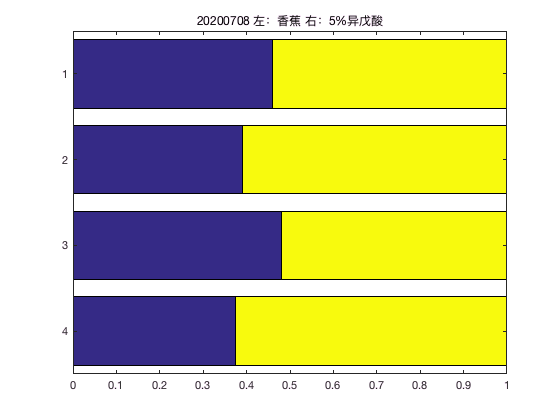

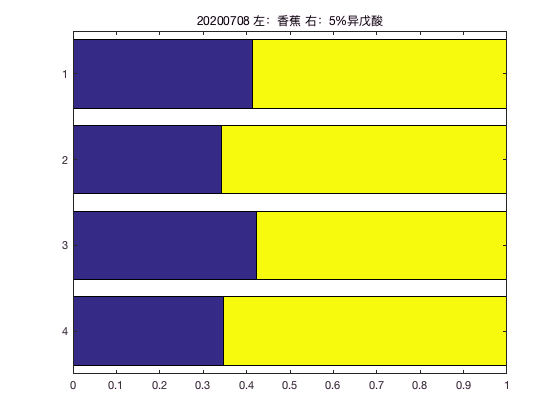

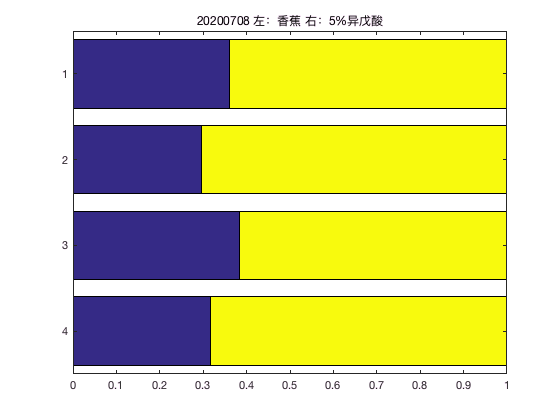

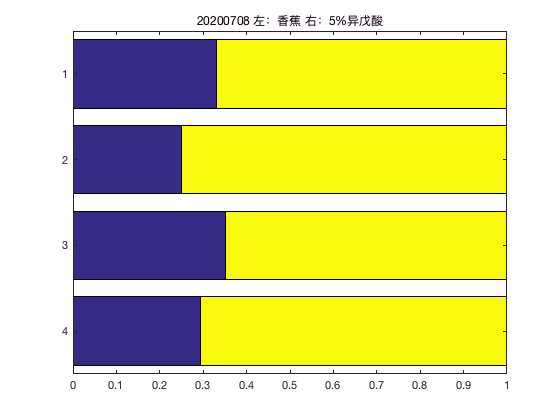

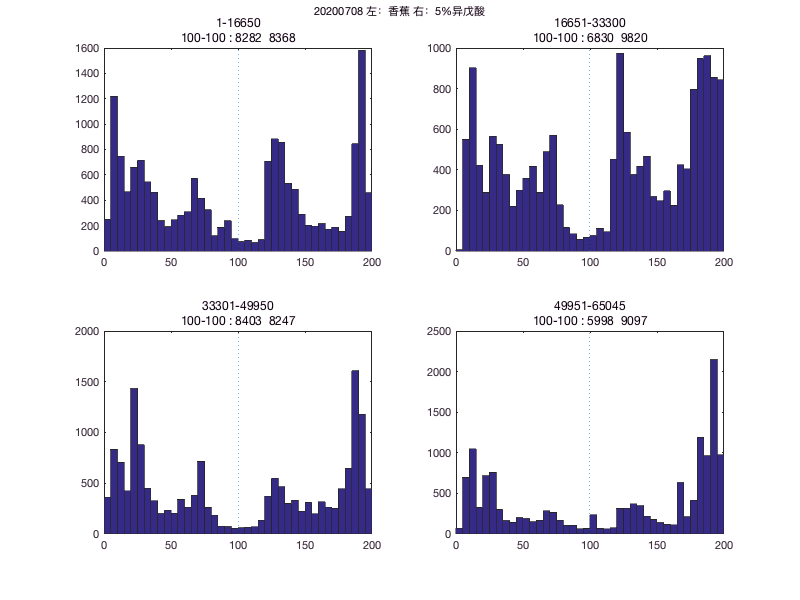

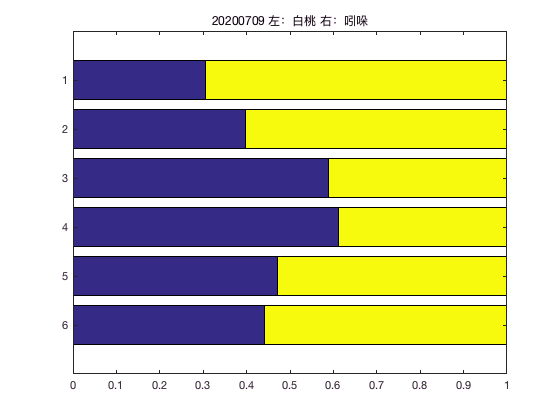

timeint=9.1;%minute
p=timeint*60*1000/40;
interval=5;
% plot each day
for f=1:length(files)
    data=alldata{f};
    l=length(data(:,2));
    plots=ceil(l/p);

    disp('===========================')
    disp(conditions{f})
    disp('===========================')
    for j=0:10:50
        timelab=zeros(1,l);
        leftright=timelab;
        cutl=100-j;
        cutr=100+j;
        leftright(data(:,2)<cutl)=1;
        leftright(data(:,2)>cutl)=2;
        for i=1:plots
            timelab(p*(i-1)+1:min(p*i,l))=i;          
        end
        timelab(leftright==0)=[];
        leftright(leftright==0)=[];
        [tbl,chi2,pvalue] = crosstab(timelab,leftright);
        disp('-------------')
        disp([num2str(cutl) '-' num2str(cutr)])
        disp(tbl)
        disp(chi2)
        disp(pvalue)
        disp('-------------')
        % barplot
        percenttbl=tbl./sum(tbl,2);
        figure;
        barh(percenttbl,'stack')
        set(gca,'YDir','reverse')
        title(conditions{f})       
    end
    
    
    figure;
    set(gcf,'position',[1280,720,ceil(plots/2)*400,2*300]);
    % subplot each bin
    for i=1:plots
        subplot(2,ceil(plots/2),i)
        hist(data(p*(i-1)+1:min(p*i,l),2),interval/2:interval:200-interval/2)
        line([100 100],get(gca,'Ylim'),'linestyle',':')
%         disp('-------------')
%         disp([num2str(p*(i-1)+1) '-' num2str(min(p*i,l))])
%         
            % chisq test
        for j=0%:10:20
            cutl=100-j;
            cutr=100+j;
%             disp([cutl cutr])
            [pvalue,st]=chit(data(p*(i-1)+1:min(p*i,l),:),cutl,cutr);
        end
%         disp('-------------')
        
        title({[num2str(p*(i-1)+1) '-' num2str(min(p*i,l))];[num2str(cutl) '-' num2str(cutr) ' : ' num2str(st.O)]})
    end
    suptitle({conditions{f};''});
end

## 绘制热图的例子 生成数据

% z = [repmat([1 2],1000,1) + randn(1000,2)*[1 .5; 0 1.32];...
%      repmat([9 1],1000,1) + randn(1000,2)*[1.4 .2; 0 0.98];...
%      repmat([4 8],1000,1) + randn(1000,2)*[1 .7; 0  0.71];];
%  
% figure('units','normalized','position',[ 0.4458    0.6296    0.1995    0.2759]);
% plot(z(:,1),z(:,2),'.');
% title({'原始数据','散点视图有显著的重叠'});
% set(gcf,'color',[1 1 1],'paperpositionmode','auto');

## 绘制热图

% xx = z(:,1);
% yy = z(:,2);
% sigma = 0.1;
% gridSize = 100;
% 
% % 选择colormap
% colormap(summer);
% 
% x=linspace(min(xx),max(xx),gridSize);
% y=linspace(min(yy),max(yy),gridSize);
% gridEval = zeros(length(x)-1,length(y)-1);
% 
% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end
% 
% % 绘制热图
% figure;
% surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% axis([min(xx),max(xx) min(yy),max(yy)]);
% h1 = gca; % 保存句柄，以便后面添加边框
% 
% % 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
% xlabel('x','Fontsize',14);
% ylabel('y','Fontsize',14);
% 
% % 添加颜色条
% colorbar;
% ylabel('Intensity','Fontsize',14);
% 
% % 添加黑色的边框
% axes(h1);
% line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
% line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
% line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
% line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);
% 
% set(gcf,'color',[1 1 1],'paperpositionmode','auto');

% %% 绘制运动的点
% % 最简单的动画形式，使用comet、comet3函数
% % 产生一个顺着曲线轨迹运动的质点
% % step1：求解出质点完整的运动轨迹坐标x，y和z
% % step2：使用comet或者comet3直接绘制动点
%  % 使用函数comet建立质点绕圆运动的动画
% clc;clear;
% %{
%  linspace是Matlab中的一个指令，用于产生指定范围内的指定数量点数，相邻数据跨度相同，并返回一个行向量。
%  调用方法：linspace(x1,x2,N)
%  功 能：用于产生x1，x2之间的N点行矢量，相邻数据跨度相同。其中x1、x2、N分别为起始值、终止值、元素个数。若缺省N，默认点数为100。
%  举例如下：X = linspace(5, 100, 20) % 产生从5到100范围内的20个数据，相邻数据跨度相同
%  X = 5 10 15 20 25 30 35 40 45 5055 60 65 70 75 80 85 90 95 100 ps：这和X = [5 : 5 : 100]的效果是一样的。
% %}
% % 圆周运动
% t = linspace(0, 2*pi, 10000);
% x = cos(t);
% y = sin(t);
% % 以便比较comet是否跟着轨迹走
% % plot(x, y);
% axis([-1, 1 -1, 1]); axis square;
% hold on; grid on;
% % comet(x, y, p); p：定义轨迹尾巴的长度，范围在0-1之间，默认时为0.1
% comet(x, y, 0.03);
%  
%  
% % 平抛运动
% clf;
% clear;
% grid on;
% vx = 40;
% dt = linspace(0,10,1000);
% dx = vx*dt;
% dy = -9.8*dt.^2/2;
% comet(dx, dy);
% 
% 
% % 导弹发射
% clf;
% clear;
% grid on;
% vx = 100*cos(1/4*pi);
% vy = 100*sin(1/4*pi);
% t = 0:0.01:15;
% dx = vx*t;
% dy = vy*t-9.8*t.^2/2;
% comet(dx, dy);
% % 使用函数comet3建立质点绕圆运动的动画
% figure();
% grid on;
% tt = 0:pi/500:10*pi;
% plot3(sin(t),cos(t),t);
% comet3(sin(tt), cos(tt), tt, 0.5); 
% 
% %% 制作动画
% clc; clear;
% % peaks是一个函数，其中有2个变量。由平移和放缩高斯分布函数获得。
% % 参数为30，得到的X、Y、Z为30*30的矩阵。
% [X, Y, Z] = peaks(30);
% % surf绘制三维曲面图
% surf(X,Y,Z);
% axis([-3,3,-3,3,-10,10]);
% % 关闭所用坐标轴上的标记、格栅和单位标记。但保留由text和gtext设置的对象
% axis off;
% %{
%  shading：是用来处理色彩效果的，分以下三种：
%  1、no shading 一般的默认模式 即shading faceted
%  2、shading flat 在faceted的基础上去掉图上的网格线
%  3、shading interp 在flat的基础上进行色彩的插值处理，使色彩平滑过渡
% %}
% shading interp;
% %{
%  colormap：设定和获取当前的色图。
%  1、colormap(map)：设置颜色图为矩阵map。如果map中的任何值在区间[0,1]之外，MATLAB返回错误。
%  2、colormap('default')：将当前的颜色图设置为默认的颜色图。
%  3、cmap=colormap：返回当前的颜色图。返回的值都在区间[0,1]内。
%  map是一个3列矩阵，其元素数值定义在区间[0,1]。矩阵的每行元素表示1一个真色彩向量，即红、绿、蓝3基色的系数。
%  jet为matlab中预定义的色图样式中的一种，表示：黑、红、黄、白色浓淡交错。
% %}
% colormap(jet);
% % 建立一个20列的大矩阵
% M = moviein(20);
% for i = 1:20
%  % 改变视点
%   view(-37.5+24*(i-1),30);
%  % 将图形保存到M矩阵
%  M(i) = getframe;
% end
% % 播放画面2次
% movie(M,2);
% %% 动态绘制椭圆
% clc;
% axis([-2,2,-2,2]);
% % axis square 当前坐标系图形设置为方形，刻度范围不一定一样，但是一定是方形的。
% % axis equal 将横轴纵轴的定标系数设成相同值，即单位长度相同，刻度是等长的，但不一定是方形的。
% axis equal;
% grid on;
% h = animatedline('Marker', 'o', 'color', 'b', 'LineStyle', 'none');
% t = 6*pi*(0:0.02:1);
% for n = 1:length(t)
%  addpoints(h, 2*cos(t(1:n)),sin(t(1:n)));
%  % 一般是为了动态观察变化过程 pause（a）暂停a秒后执行下一条指令
%  pause(0.05);
%  % 可以用drawnow update加快动画速度
%  drawnow update;
% end